%1-A
mat1 = [250 50 250 50 250; 50 250 50 250 50; 250 50 250 50 250; 50 250 50 250 50; 250 50 250 50 250]

mat1 =    250    50   250    50   250
    50   250    50   250    50
   250    50   250    50   250
    50   250    50   250    50
   250    50   250    50   250


mat2 = [250 255 250 240 250; 101 98 102 120 240; 250 110 250 99 250; 250 250 101 100 250; 250 255 250 255 250]

mat2 =    250   255   250   240   250
   101    98   102   120   240
   250   110   250    99   250
   250   250   101   100   250
   250   255   250   255   250


mat3 = [50 50 50 50 50; 50 250 250 250 50; 50 250 10 250 50; 50 250 250 250 50; 50 50 50 50 50]

mat3 =     50    50    50    50    50
    50   250   250   250    50
    50   250    10   250    50
    50   250   250   250    50
    50    50    50    50    50



sig1 = [0.077847 0.123317 0.077847; 0.123317 0.195346 0.123317; 0.077847 0.123317 0.077847]

sig1 =     0.0778    0.1233    0.0778
    0.1233    0.1953    0.1233
    0.0778    0.1233    0.0778


sig2 = [0.102059 0.115349 0.102059; 0.115349 0.130371 0.115349; 0.102059 0.115349 0.102059]

sig2 =     0.1021    0.1153    0.1021
    0.1153    0.1304    0.1153
    0.1021    0.1153    0.1021



%Set one with sigma = 1
imfilter(mat1, sig1, 'conv')

ans =    80.6299  110.0397  106.2575  110.0397   80.6300
  110.0397  151.3469  148.6537  151.3469  110.0397
  106.2576  148.6537  151.3469  148.6537  106.2575
  110.0397  151.3469  148.6537  151.3469  110.0397
   80.6300  110.0397  106.2576  110.0397   80.6299


imfilter(mat2, sig1, 'conv')

ans =   100.3664  139.3597  139.4274  149.9633  117.3703
  121.8877  167.0350  163.2712  185.2674  149.7297
  132.7764  169.1881  143.8602  162.0755  138.5966
  169.7384  214.9785  180.5214  184.3201  150.3845
  130.5733  169.6253  151.4296  151.1277  118.8963


imfilter(mat3, sig1, 'conv')

ans =    41.5607   76.2823   91.8517   76.2824   41.5607
   76.2824  135.2822  164.6022  135.2822   76.2823
   91.8518  164.6022  203.1175  164.6022   91.8517
   76.2823  135.2822  164.6022  135.2822   76.2823
   41.5607   76.2823   91.8517   76.2823   41.5607



%Set two with sigma = 2
imfilter(mat1, sig2, 'conv')

ans =    69.6424  103.2362  100.9246  103.2362   69.6424
  103.2362  157.7215  142.2793  157.7215  103.2362
  100.9246  142.2793  157.7215  142.2793  100.9246
  103.2362  157.7215  142.2793  157.7215  103.2362
   69.6424  103.2362  100.9246  103.2362   69.6424


imfilter(mat2, sig2, 'conv')

ans =    83.6588  122.9413  123.7050  137.7096  100.2073
  119.3977  180.3536  167.9680  196.2562  137.4034
  121.2852  168.6974  138.0860  166.6849  122.9863
  156.3560  217.2416  184.5945  196.4171  137.9310
  116.3587  155.5791  138.7916  138.2767  101.0499


imfilter(mat3, sig2, 'conv')

ans =    43.5682   77.5084   97.9202   77.5084   43.5682
   77.5084  118.1316  158.4236  118.1316   77.5084
   97.9202  158.4236  218.7117  158.4236   97.9202
   77.5084  118.1316  158.4236  118.1316   77.5084
   43.5682   77.5084   97.9202   77.5084   43.5682



%As for the difference, there is a slight deduction between the 
%sigma being 1 (greater) and the sigma being 2 (lesser)

%1-B
xcorr2(mat1, mat2)

ans =        62500       76250      137750      152500      213000      152500      137750       76250       62500
       75000      112750      181500      255550      332750      255550      189000      150250       75000
      137500      181000      310250      335000      528500      335000      348300      191250      137500
      147500      222200      322750      462600      544150      455650      297150      247800      112750
      212000      319500      494350      580150      817400      545400      520700      297650      205050
      147500      221450      319000      461850      540400      454900      297150      247800      112750
      137000      175750      314050      322400      486850      287650      302900      146400      130050
       72500      116500      176500      221350      282900      214400      144400      104800       37750
       62500       72500      137000      148750      212250      148750      137750       76250       62500


%1: Outside region is has less density
%2: Density increases greatly as you move inward
%3: As the density becomes greater, correlation is greater
%4: Both values from images do correlate closely together
%5: Differences can be seen as the values decrease

%1-C
imgradient(mat1)

ans =   565.6854         0         0         0  565.6854
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
  565.6854         0         0         0  565.6854


imgradient(mat2)

ans =   604.1192  611.0008  573.4614  421.2458  212.1320
  202.2523  290.0069  286.5659  394.5884  425.0671
  662.4877  475.6133  198.4943  288.6694  572.0874
  198.1161  415.8173  432.8071  431.4487  472.4955
   15.8114  217.9036  481.9378  482.5785  205.5480


imgradient(mat3)

ans =   282.8427  632.4555  800.0000  632.4555  282.8427
  632.4555  509.1169  320.0000  509.1169  632.4555
  800.0000  320.0000         0  320.0000  800.0000
  632.4555  509.1169  320.0000  509.1169  632.4555
  282.8427  632.4555  800.0000  632.4555  282.8427


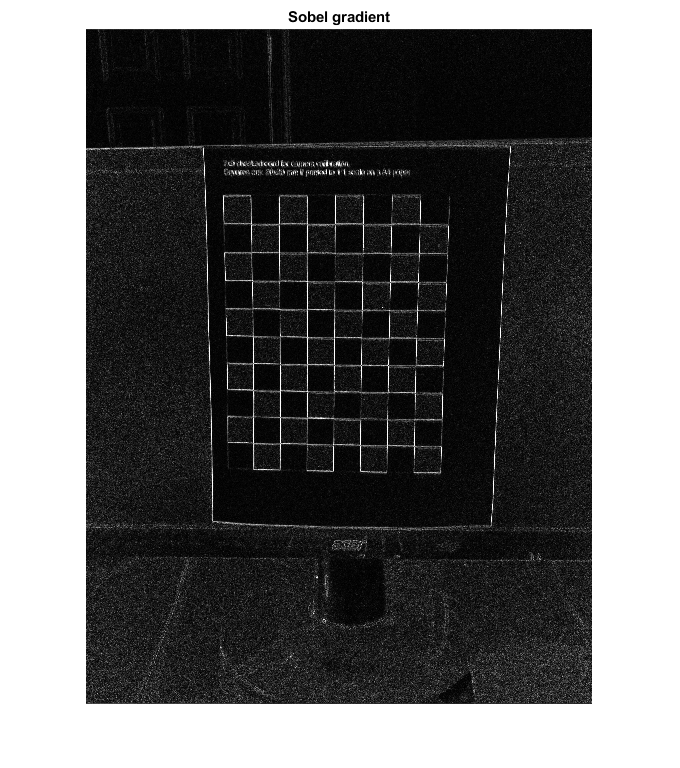


%1-D
%Pseudo-code
im=imread('C:\Users\bengo\Downloads\test1.jpg');
B=rgb2gray(im);
C=double(B);
for i=1:size(C,1)-2
    for j=1:size(C,2)-2
        %Sobel mask for x-direction:
        Gx=((2*C(i+2,j+1)+C(i+2,j)+C(i+2,j+2))-(2*C(i,j+1)+C(i,j)+C(i,j+2)))
        %Sobel mask for y-direction:
        Gy=((2*C(i+1,j+2)+C(i,j+2)+C(i+2,j+2))-(2*C(i+1,j)+C(i,j)+C(i+2,j)))
        B(i,j)=sqrt(Gx.^2+Gy.^2)
    end
end
imshow(B)


%Edge Validation
im = imread('C:\Users\bengo\Downloads\test1.jpg')

im = 4048×3036×3 uint8 array
im(:,:,1) =

  Columns 1 through 1666

   244   244   244   244   244   245   245   245   244   245   243   243   244   245   245   243   246   244   245   247   246   244   244   244   243   242   243   246   247   244   243   243   244   243   243   244   244   244   244   245   241   242   243   244   246   247   247   246   243   244   244   244   242   241   242   244   245   245   246   247   246   245   244   244   245   245   244   241   239   237   236   239   242   241   230   223   220   219   220   219   218   214   212   212   211   210   212   211   211   210   210   212   212   213   212   212   214   215   215   216   219   219   217   217   218   220   223   227   227   228   229   229   231   233   233   233   235   236   237   238   237   238   239   239   239   238   239   240   243   241   240   240   240   240   240   240   240   240   240   239   239   240   240   241   241   238   239   241   240   239   240   241   239   237   238  

I = rgb2gray(im)

I = 4048×3036 uint8 matrix
   233   233   233   233   233   234   235   235   234   235   235   235   236   237   237   235   236   234   235   237   236   234   234   234   233   232   233   236   237   234   233   233   236   235   235   236   236   236   236   237   233   234   235   236   236   237   237   236   235   236
   232   233   233   233   234   235   236   236   235   236   236   235   235   236   236   235   235   234   235   236   235   235   237   236   232   231   232   235   235   234   233   233   235   235   235   235   235   234   235   237   236   234   232   232   236   238   238   236   234   234
   231   232   233   233   234   234   235   234   236   236   235   234   234   235   236   236   236   236   236   234   232   233   235   234   232   232   233   234   235   235   235   235   234   235   235   235   233   233   235   238   237   237   235   234   235   236   237   237   236   235
   232   233   233   233   233   234   234   233   235   235   235   2

BW1 = edge(I, 'Canny')

BW1 = 4048×3036 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

BW2 = edge(I, 'Prewitt')

BW2 = 4048×3036 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

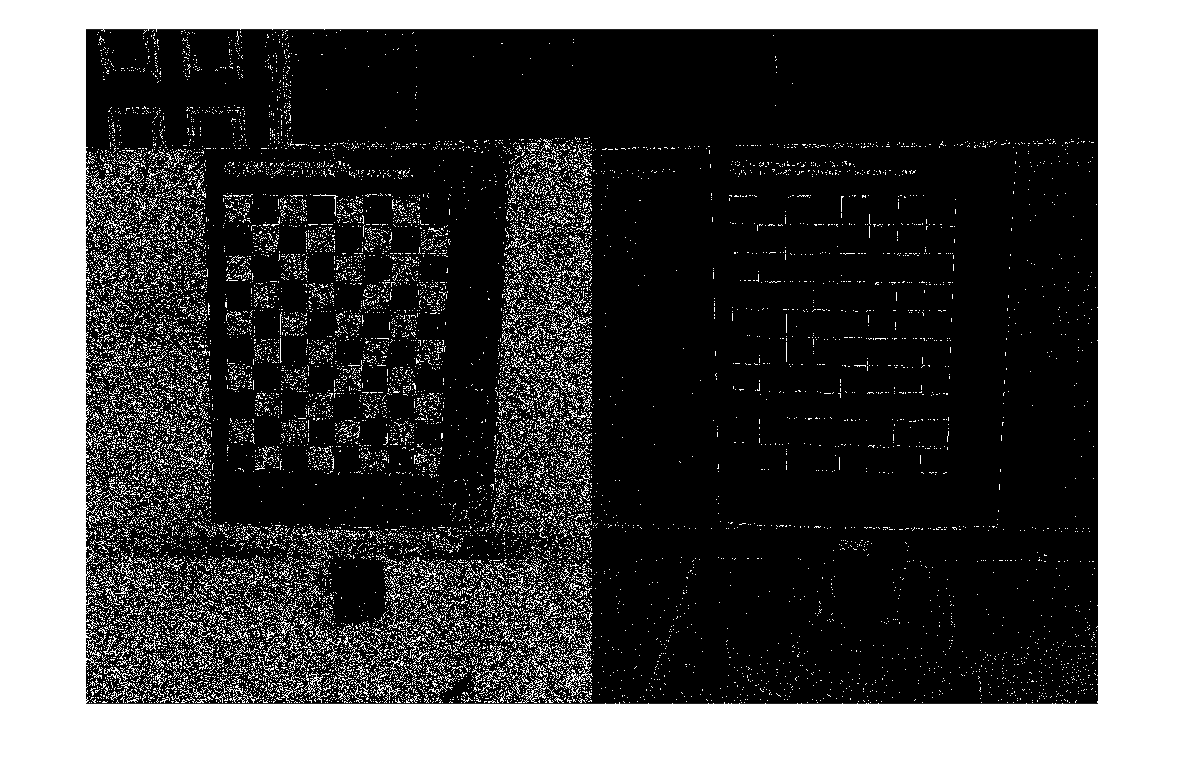

imshowpair(BW1,BW2,'montage')